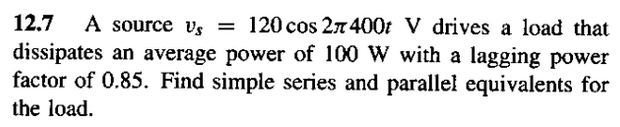

clc, clear, close all
format short g

vf = 120;
f = 400;
w = 2*pi*f;

pa = 100;
fp = 0.85;


ya que tenemos la potencia activa, calculamos la potencia aparente:

s = pa/fp

s =        117.65


Con el factor de potencia en atraso, sabemos que es una carga inductiva, y como el angulo del factor de potencia es el mismo angulo de la impedancia:

angulo = acos(fp)

angulo =       0.55481


calculamos el componente resistivo de la carga y la reactancia inductiva:

r = (((vf/sqrt(2))*fp)^2)/pa

r =         52.02


xl = r*tan(angulo)

xl =        32.239


z = r+j*xl %impedancia total de la carga

z =         52.02 +     32.239i


**Ahora encontramos el equivalente en serie **

rs = r

rs =         52.02


ls = (xl/w)*1000

ls =        12.828


Calculamos la corriente para hacer la verificacion en el simulador

i_f = (vf/z)/sqrt(2);
i_f = [abs(i_f) angle(i_f)*180/pi] 

i_f =        1.3865      -31.788


Lo verificamos en el simulador:

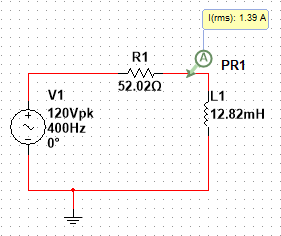

**Equivalente en paralelo**

rp = ((r^2)+(xl^2))/r %ohms

rp =            72


lp = (((r^2)+(xl^2))/(w*xl))*1000 %mH

lp =        46.225


lo verificamos en el simulador: